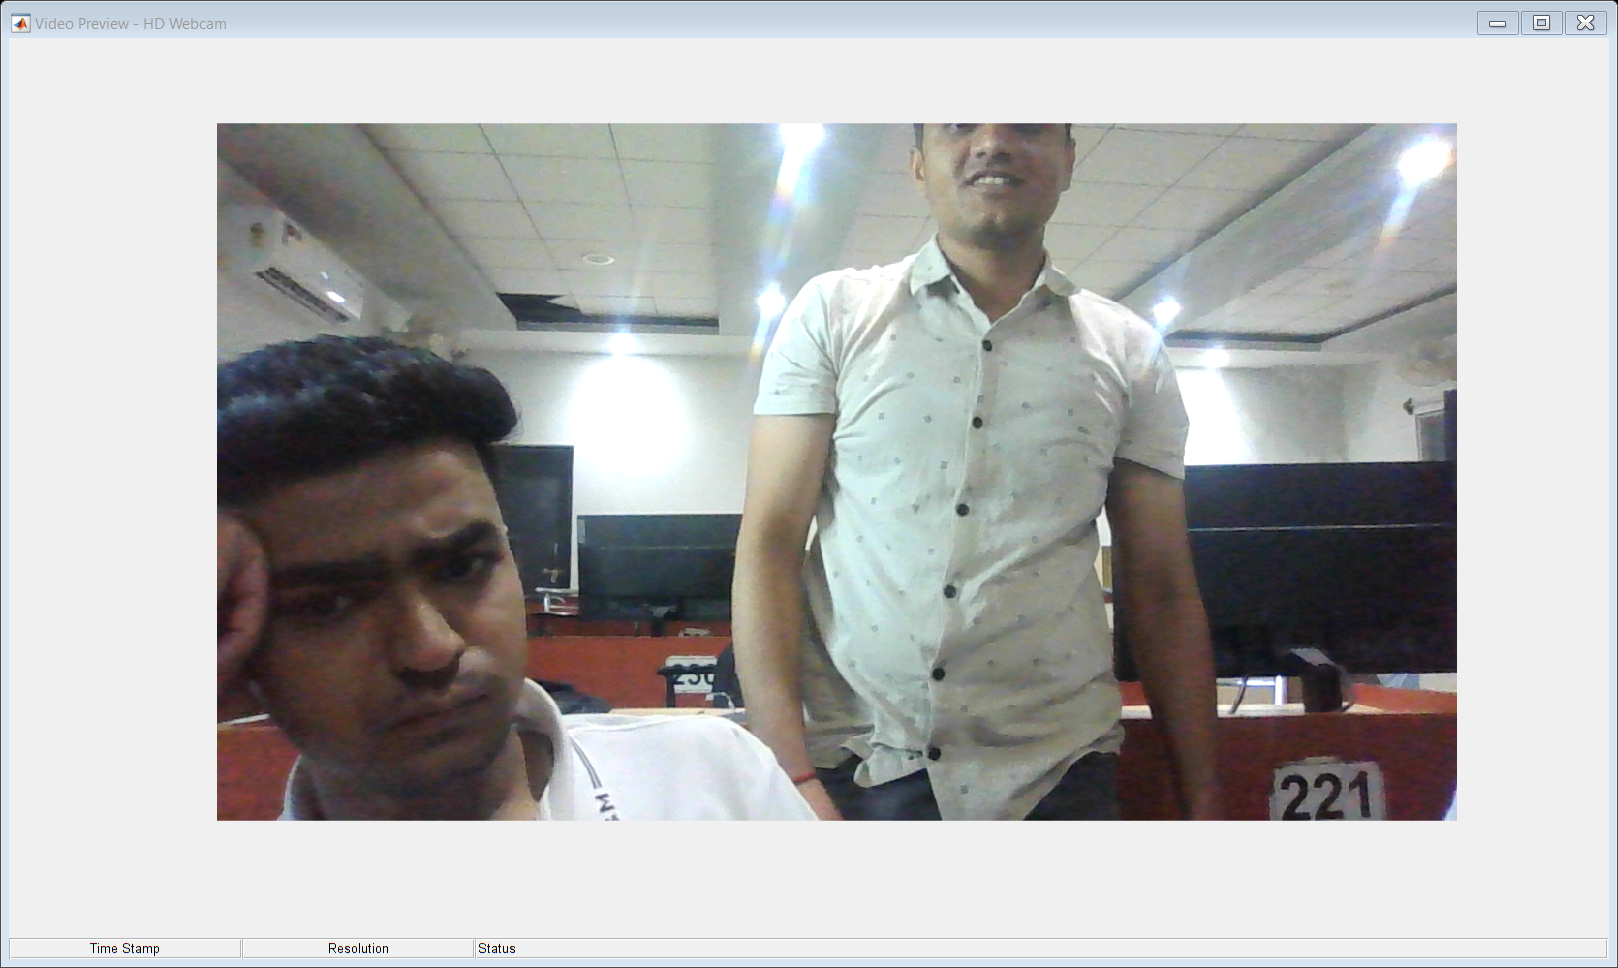

clear;
close all;

camObj = webcam(1);
preview(camObj);

boxImage = imread(me.jpg');

Unable to resolve the name 'me.jpg'.


boxImage=rgb2gray(boxImage);

figure;imshow(boxImage);title('Image of a Box');

while(1)
sceneImage1 = snapshot(camObj);

sceneImage=rgb2gray(sceneImage1);

boxPoints = detectSURFFeatures(boxImage);

scenePoints = detectSURFFeatures(sceneImage);

[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);

[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

boxPairs = matchFeatures(boxFeatures, sceneFeatures);

matchedBoxPoints = boxPoints(boxPairs(:, 1), :);

matchedScenePoints = scenePoints(boxPairs(:, 2), :);

len=length(matchedScenePoints);


if len >20

[tform, inlierBoxPoints, inlierScenePoints] =estimateGeometricTransform(matchedBoxPoints, matchedScenePoints, 'affine');

boxPolygon = [1, 1;... % top-left

size(boxImage, 2), 1;... % top-right

size(boxImage, 2), size(boxImage, 1);... % bottom-right

1, size(boxImage, 1);... % bottom-left

1, 1]; % top-left again to close the polygon

newBoxPolygon = transformPointsForward(tform, boxPolygon);

d='Object Recognized'

currFrame=sceneImage1;

position = [321 430];

box_color = {'yellow'};

RGB = insertText(currFrame,position,d,'FontSize',22,'BoxColor', box_color,'BoxOpacity',0.9);

imshow(RGB);

hold on;

line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), 'Color', 'y');

title('Detected Box');

else

d='Object Not Recognized'

currFrame=sceneImage1;

position = [321 430];

box_color = {'red'};

RGB = insertText(currFrame,position,d,'FontSize',22,'BoxColor',box_color,'BoxOpacity',0.9);

imshow(RGB);

end
end